# MHKit Upcrossing Analysis Example

The following example shows how to perform an upcrossing analysis on a surface elevation trace and plot quantities of interest (such as wave heights, periods, and crest exceedance probabilities).


% Clear variables and close figures
clear; close all;

## Compute the Surface Elevation

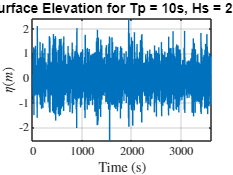


% Define Peak Period and Significant Wave Height
Tp = 10;        % Peak period in seconds
Hs = 2.5;       % Significant wave height in meters
gamma = 3.3;    % JONSWAP 

% Define Frequency Vector using a return period of 1 hour
Tr = 3600;      % Return period in seconds (1 hour)
df = 1 / Tr;    % Frequency step size in Hz
f = 0:df:1;     % Frequency vector

% Calculate JONSWAP Spectrum
spec = jonswap_spectrum(f, Tp, Hs, gamma); 

% Sampling frequency for time vector
fs = 10.0;              % Sampling frequency in Hz
t = 0:1/fs:Tr-1/fs;     % Time vector

% Generate Surface Elevation
eta = surface_elevation(spec, t); 

% Plot Surface Elevation
figure();
plot(eta.time, eta.elevation);
xlabel('Time (s)','interpreter','latex');
ylabel('$\eta (m)$','interpreter','latex');
title(['Surface Elevation for Tp = ' num2str(Tp) 's, Hs = ' num2str(Hs) 'm']);
grid on; set(gca,'TickLabelInterpreter','latex')
xlim([eta.time(1) eta.time(end)])

## Plot the Individual Wave Heights and Periods

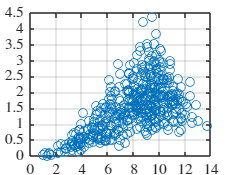

waveHeights = uc_heights(t, eta.elevation);
wavePeriods = uc_periods(t, eta.elevation);


figure();
plot(wavePeriods, waveHeights, 'o');
xlabel('Zero Crossing Period (s)','interpreter','latex');
ylabel('Wave Height (m)','interpreter','latex');
grid on;set(gca,'TickLabelInterpreter','latex')

## Plot the Crest Probability of Exceedance Distribution

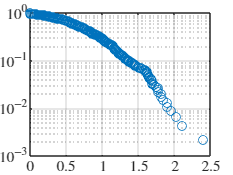

crests = uc_peaks(t, eta.elevation); 
crests_sorted = sort(crests);

% Number of crests
N = numel(crests_sorted);

% Exceedance probability (ascending crests)
Q = (N:-1:1) / N;

% Plot Exceedance Probability
figure();
semilogy(crests_sorted, Q, 'o');
xlabel('Crest Height (m)','interpreter','latex');
ylabel('P(Exceedance)','interpreter','latex');
grid on; set(gca,'TickLabelInterpreter','latex')